## 2.4.1

### PROBLEM 2.

#### <PART 2>

Choose a partial Fourier Series approximation $p_n \left(t\right)$ for $f\left(t\right)$. Then plot $p_n \left(t\right)$and $f\left(t\right)$ on the same graph. Compute the error.

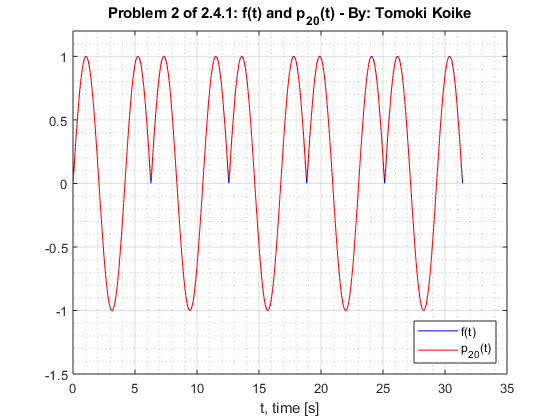

% Defining f(t)
prp = 2*pi; % Pulse repitetion period
pw = 2*pi; % Pulse width
fs = 1000; % Sample frequency
period = 2*pi*5; % Period to plot graph
T = 0:1/fs:period-1/fs; % Time to map t
D = 0:prp:period-prp; % Delay
f = pulstran(T,D,@(t)sin(1.5 .* t).*(t>=0).*(t<pw));

% Defining the partial Fourier Series Approximation for n = 20
p_20 = 2/3/pi;
for k = 1:20
    p_20 = p_20 - 12 / pi / (2*k+3) / (2*k-3) * cos(k .*T);
end

% Plotting 
figure(1)
plot(T, f, '-b')
xlabel('t, time [s]')
title('Problem 2 of 2.4.1: f(t) and p_2_0(t) - By: Tomoki Koike')
grid on
grid minor
box on
hold on
plot(T, p_20, '-r')
hold off
ylim([-1.5 1.2])
legend('f(t)', 'p_2_0(t)','Location', 'southeast')